# **METODO DE LA BISECCIÓN - LIVE SCRIPT**

clc, clear;
format long g;
syms x;

**INGRESAR EL X DE DATO INFERIOR:**

Lim_inf = 0;

**INGRESAR EL X DE DATO SUPERIOR:**

Lim_sup = 8;

**INGRESAR LA TOLERACIA:**

Tol     = 0.0001;

**INGRESAR EL NUMERO DE ITERACIONES:**

Num_it  = 20;

**INGRESAR LA ECUACÍON:**

f_x= -1.654*0.44+9.36*log10(x+1)-0.2+ ( (log10(1.7/(4.2-1.5)))/ (0.4+ 1094/(x+1)^5.19) )+2.32*log10(16246.71)-8.07-log10(2.35*10^7)

$$f\_x = \frac{234\,\log\left(x+1\right)}{25\,\log\left(10\right)}-\frac{7238720088643383}{36028797018963968\,\left(\frac{1094}{{\left(x+1\right)}^{519/100}}+\frac{2}{5}\right)}-\frac{5805291272460659783}{879609302220800000}$$

**=========================================================================================================================**

**=========================================================================================================================**

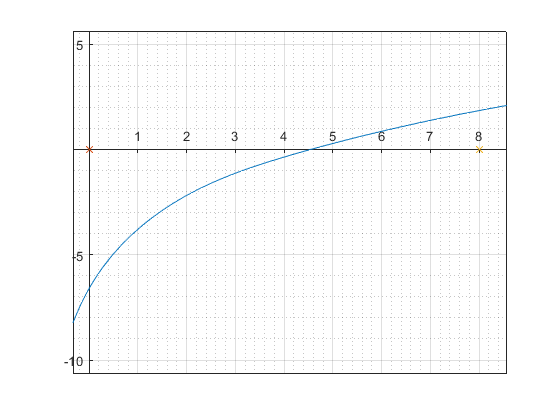

n=[1 2];
a_n=[1 2];
b_n=[1 2];
p_n=[1 2];
f_n=[1 2];

fplot(f_x);
hold on;
plot(Lim_inf,0,'x');
plot(Lim_sup,0,'x');
hold off;
grid on;
grid minor;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

f= @(x) eval(f_x);
i=1;
FA=f(Lim_inf)

FA =           -6.6000356526584


FB=f(Lim_sup)

FB =           1.84444166036704


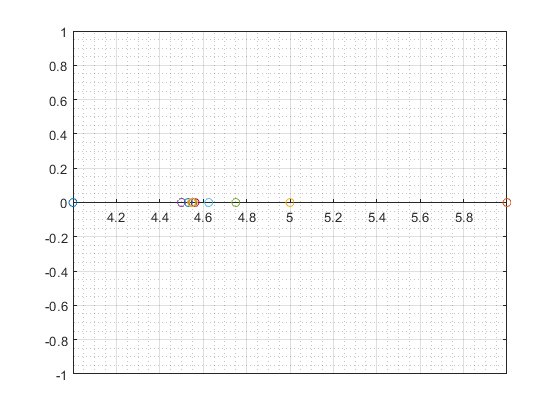

          4.54779052734375



      2.83557216125274e-05



while(i<=Num_it)
    p=Lim_inf+(Lim_sup-Lim_inf)/2;
    FP=f(p);
    plot(p,0,'o');
    hold on;
    grid on;
    grid minor;
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    
    n(i)=i;
    a_n(i)=Lim_inf;
    b_n(i)=Lim_sup;
    p_n(i)= p;
    f_n(i)=FP;

     if((FP==0) || ((Lim_sup-Lim_inf)/2) < Tol ) 
         disp(p);
         disp(FP);         
         break;
     end
     
     if(FA*FP>0)
         Lim_inf=p;
         FA=FP;
        
     else
         Lim_sup=p;
         FB=FP;
         
     end
     i=i+1;
end

tabla=[n' a_n' b_n' p_n' f_n'];

NUM_IT=n';
An=a_n';
Bn=b_n';
Pn=p_n';
Fn=f_n';

Resultados = table(NUM_IT,An, Bn ,Pn, Fn)

Resultados = 17×5 table
    NUM_IT          An               Bn               Pn                    Fn          
    ______    ______________    ____________    _______________    _____________________

       1                   0               8                  4       -0.362905296712954
       2                   4               8                  6         0.85874485918522
       3                   4               6                  5        0.281890273459963
       4                   4               5                4.5      -0.0306173893480404
       5                 4.5               5               4.75        0.127824721389913
       6                 4.5            4.75              4.625       0.0491754878345558
       7                 4.5           4.625             4.5625      0.00942586036695836
    

xlswrite('RESULTADOS.xlsx',tabla)   



